# LAB 2 | Build-Your-Own Planet!

## Planetesimal Accretion Model

This exercise uses a simplified gravitational *n*-body model to simulate planetary accretion through planetesimal collisions and the compositional evolution of planetary embryos.

Planetesimals are initialised with random masses and positions within a disk extending to ~20 AU. A gas giant can optionally be placed at 5 AU from the central star.

The model tracks three components—metal, rock, and ice—assuming a radial distribution: metal- and rock-rich in the inner disk, ice-dominated beyond the snow line at 5 AU.

Collisions occur when bodies pass within an effective collision radius. The colliding masses, compositions, and momenta merge into a single body, positioned at the centre of mass and moving with momentum-conserving velocity.

## Task 1 – First Look

Begin by running the model with the default parameters set in the demo case. Click the **Run** button (green triangle) in the menu bar. To stop the simulation, click **Stop** (red square).

Output figures are saved in the `out/` folder of your MATLAB Drive or current working directory. Review the numbered frames to see how the accretion model evolves over time. What patterns do you notice?

Each time frame produces three figures:

- a **top view** of the protoplanetary disk,

- a **radial view** of the disk, and

- a **planetary zoo plot** of planetary radius vs. mass (relative to Earth).

In the disk views, body sizes are scaled to radius, with colours showing composition (red = metal core, green = rocky mantle, blue = icy envelope). The Sun and a gas giant appear in black (not to scale). For orientation, Earth’s orbit and size are indicated. The five most massive bodies are highlighted in magenta and shown at 3× magnification in the radial views.

## Task 2 – Parameter Testing

At the end of the script you will find several model parameters that can be adjusted within preset ranges. Explore these options and test a few variations. You only need to run each simulation briefly to see the effect of a new parameter set.

To save output figures separately for each test, assign a new run identifier each time. Use clear `Run IDs`, e.g. `NumberBodies500` for a run initialised with 500 bodies.

You can also change the `random seed`, which controls the initial random distribution of planetesimals. Adjusting this number produces unique outcomes for otherwise identical parameter sets.

## Task 3 –  Number and Mass of Planetesimals

Run three simulations with varying initial numbers and masses of planetesimals:

- 1000 bodies, average mass 0.01

- 300 bodies, average mass 0.03

- 2000 bodies, average mass 0.005

Set the stopping time to at least 100 years and increase the output interval to 300 or more to avoid excessive figures.

In each case, the total mass is similar, but distributed across different numbers of bodies. What differences do you observe in the simulation outcomes?

## Task 4 – Effects of a Gas Giant

The model includes a **gas giant **orbiting at 5 AU. Gas giants are thought to form early in protoplanetary disks, when icy particles and gas are abundant beyond the snow line. Their large mass strongly influences nearby orbits and the formation of later planets.

Run three simulations with gas giant masses of 10, 100, and 1000 Earth masses. Assign a new `Run ID` for each case, and run to at least 100 years with the output interval set to 300 or higher.

Which case corresponds roughly to Jupiter’s mass in our solar system? What differences do you observe as the gas giant becomes more massive?

## Task 5 – Final Simulation

The model artificially increases collision likelihood so that planets form within a manageable runtime. For this last test, increase the collision detection distance to 0.1 and run the model with as many bodies, and for as long, as time (and patience) allow.

At the final state, describe the five most massive bodies formed. Do they resemble any planets in our solar system? Comparing their mass and radius (relative to Earth’s radius shown on the plots) with the exoplanetary zoo figure, where would they fall? Terrestrial planet, super-Earth, water world, or ice giant?

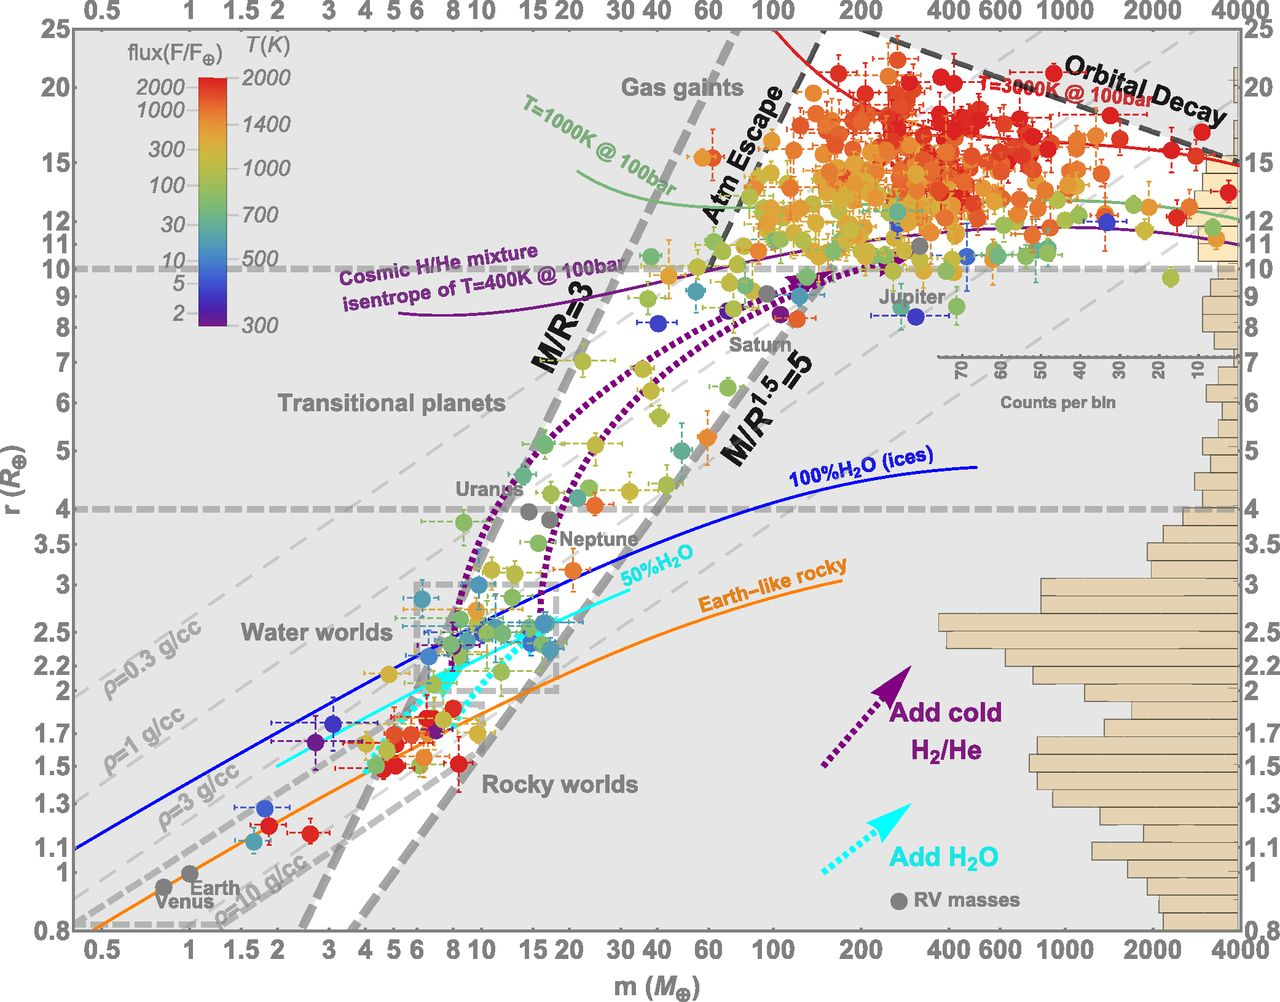

**Figure:** Exoplanetary Zoo after Zeng et al., *PNAS*, 2019 showing radius vs. mass of confirmed exoplanet discoveries. Data shown relative to Earth, with colour indicating estimated surface temperature and some trends indicating typical compositional categories. 

# Set Model Parameters

clear; close all; clc;  % clear workspace

Set run identifier tag. Output figures will be saved to folder `out/runID`. Set new identifier for every model run.

runID = 'byoplanet';  % change RunID for every parameter test

Set seed for random number generator. Adjust the slider to your favourite number to produce uniquely randomised results.

rng(15);  % change the random seed

Set interval of time steps between plotting and saving figures. Select lower interval for testing, higher for full model run.

nop  =  100;  % select lower interval for testing, higher interval for full run

Set model stopping time in years. Select shorter stopping time for testing, higher for full run. 

tend  =  1000;  % select shorter stopping time for testing, higher for full run

Set initial condition for *n-*body simulation. Select the number of planetesimals, their mean mass, the mass of the gas giant planted at 5 AU, and the mass of the central star. All masses are given in Earth Masses.

N     = 1000;  % initial number of bodies
MPls  = 0.03;  % mean planetesimal mass [Earth Masses]
MGgt  = 300;  % mass of gas giant [Earth Masses]
MStr  = 3e5;  % mass of central star [Earth Masses]

Set effective collision radius: the radial distance [AU] to which nearby bodies are merged as collisions.

cls   = 0.03;  % collision radius [AU]

% create output directory
if ~exist(['./out/',runID],'dir'); mkdir(['./out/',runID]); end

% initialise body mass and position
M  = [MStr; MGgt; min(MPls*100,max(MPls/100,normrnd(MPls,MPls/4,N-2,1)))];  % body mass
X  = [0,0,0; 5,0,0; randn(N-2,3).*[6,6,1/3]];  % body position
r  = sum((X-X(1,:)).^2,2).^0.5 + eps^2;  % radial distance to sun

% initialise body composition (metal = 1, rock = 2; ice = 3)
Cmtl = min(1,max(0,0.5-r.^0.5./6 + randn(N,1)./100));
Crck = 1-Cmtl;
Cice = min(30,max(0,3.*max(0,r-5).^0.5) .* (1 + randn(N,1)./20));
C    = [Cmtl,Crck,Cice]./(Cmtl+Crck+Cice);

% calculate radii
Rtot = sum(M.*C(:,1:3)./[2,1,0.5]+eps,2).^(1/3);
Rrck = sum(M.*C(:,1:2)./[2,1    ]+eps,2).^(1/3);
Rmtl = sum(M.*C(:,1:1)./[2      ]+eps,2).^(1/3);
Rsun = (M(1)/0.5).^(1/3);
Rggt = (M(2)/0.5).^(1/3);
Rear =    (1/1.5).^(1/3);

% calculate initial orbital velocity
R  = (X-X(1,:))./r;
V  = sqrt(M(1)./r) .* [R(:,2),-R(:,1),R(:,3)] .* (1+randn(N,3).*[0 0 0;0 0 0;ones(N-2,1).*[0.1,0.1,0.5]]);

% calculate duration of 1 year (orbital period for body of M = 1, R = 1)
yr = 2*pi/sqrt(M(1));

% calculate time step size
dt = yr/100;

CLS  = 0;  % initialise collision count
time = 0;  % initialise time
k    = 0;  % initialise time step counter

% print start of simulation
fprintf(1,'\n\n*****  Start B-Y-O Planet Simulation  *****\n\n')

% main time stepping loop
while time-dt <= tend*yr
    
    % store previous position
    Xo = X;
    
    % calculate new orbital velocity
    for nj = 1:N
        D  = sum((X-X(nj,:)).^2,2).^0.5 + 1e-16;
        Fj = - (M.*M(nj))./D.^2 .* (X-X(nj,:))./D;
        V  = V + Fj./M .* dt;
    end
    V = V - V(1,:);
    
    X  = Xo + V.*dt;  % update position of all bodies
    r  = sum((X-X(1,:)).^2,2).^0.5 + 1e-32;  % update radial distance to sun

    % detect collisions
    nj = 1;
    while nj < N
        Do      = sum((Xo-Xo(nj,:)).^2,2).^0.5 + 1e-16;
        D       = sum((X -X (nj,:)).^2,2).^0.5 + 1e-16;
        ind     = (D+Do)./2 < cls;
        ind(nj) = 0;
        ind     = find(ind>0);
        
        % merge collided bodies
        for i = 1:length(ind)
            Mc        = M(ind(i));
            Vc        = V(ind(i),:);
            X(nj,:)   = ((M(ind(i)).*X(ind(i),:)) + M(nj).*X(nj,:))./(M(ind(i))+M(nj));
            V(nj,:)   = ((M(ind(i)).*V(ind(i),:)) + M(nj).*V(nj,:))./(M(ind(i))+M(nj));
            C(nj,:)   = ((M(ind(i)).*C(ind(i),:)) + M(nj).*C(nj,:))./(M(ind(i))+M(nj));
            M(nj)     = M(ind(i))+ M(nj);
            N         = N-1;
        end
        
        % remove consumed bodies
        X(ind,:)  = [];
        Xo(ind,:) = [];
        r(ind,:)  = [];
        V(ind,:)  = [];
        C(ind,:)  = [];
        M(ind)    = [];
        Rtot(ind) = [];
        
        CLS = CLS + length(ind); % update collision counter
        nj  = nj+1; % move to check collisions for next body
    end
    
    % update radii
    Rtot = sum(M.*C(:,1:3)./[2,1,0.5]+1e-16,2).^(1/3);
    Rrck = sum(M.*C(:,1:2)./[2,1    ]+1e-16,2).^(1/3);
    Rmtl = sum(M.*C(:,1:1)./[2      ]+1e-16,2).^(1/3);
    Rice = Rtot - Rrck - Rmtl;

    if ~mod(k,10); fprintf(1,'   -- %d;  time = %4.2f years;  bodies = %d;  collisions = %d\n',k,time/yr,N,CLS); end
    
    % plot and print model progress
    SCL = 200;
    scl = [1/20,2];
    if ~mod(k,nop) || time-dt >= tend*yr
        figure(1); clf; set(gcf,'Visible','on','PaperUnits','centimeters','PaperSize',[24,18]);
        rectangle('Position',[-1 -1  2  2],'Curvature',[1,1],'EdgeColor','k','LineStyle',':','LineWidth',2); hold on; box on; axis equal;
        rectangle('Position',[-5 -5 10 10],'Curvature',[1,1],'EdgeColor','k','LineStyle',':','LineWidth',2);
        scatter(X(3:N,1),X(3:N,2),Rtot(3:N).^2.*SCL,[0,0,1],'filled');
        scatter(X(3:N,1),X(3:N,2),Rrck(3:N).^2.*SCL,[0,1,0],'filled');
        scatter(X(3:N,1),X(3:N,2),Rmtl(3:N).^2.*SCL,[1,0,0],'filled');
        scatter(X(1:2,1),X(1:2,2),[Rsun,Rggt].^2.*scl,zeros(2,3),'filled');
        
        [~,I] = sort(M,'descend');
        [~,J] = sort(r(I(3:7)),'ascend');
        for n = 1:5
            ind = I(J(n)+2);
            scatter(X(ind,1),X(ind,2),(Rtot(ind)+0.01).^2.*SCL,[1,0,1],'LineWidth',1.5)
        end
        
        scatter(-9,-8,Rear^2.*SCL,[0,0,0]);
        scatter(-9,-9,Rggt^2.*scl(2),[0,0,0],'filled');
        text(-8,-8,'Earth','FontSize',13);
        text(-8,-9,'star, gas giant not to scale','FontSize',13);
        
        text(0.025,0.95,[num2str(time/yr,4),' years'],'Units','normalized','FontSize',13);
        text(0.025,0.90,[int2str(N  ),' bodies'    ],'Units','normalized','FontSize',13);
        text(0.025,0.85,[int2str(CLS),' collisions'],'Units','normalized','FontSize',13);
        
        axis([X(1,1)-10,X(1,1)+10,X(1,2)-10,X(1,2)+10]);
        title('Accretionary Disk – Top View','FontSize',15);
        xlabel('Distance [AU]','FontSize',15)
        ylabel('Distance [AU]','FontSize',15)
        
        drawnow;
        print(gcf,['./out/',runID,'/',runID,'_top_',int2str(k/nop)],'-dpdf','-vector','-fillpage');
        
        
        figure(2); clf; set(gcf,'Visible','on','PaperUnits','centimeters','PaperSize',[24,18]);
        line([1,1],[-1,1],'Color','k','LineStyle',':','LineWidth',2); hold on; box on; axis equal;
        line([5,5],[-1,1],'Color','k','LineStyle',':','LineWidth',2); hold on; box on; axis equal;
        scatter(r(3:N),X(3:N,3),Rtot(3:N).^2.*SCL,[0,0,1],'filled'); hold on; box on; axis equal;
        scatter(r(3:N),X(3:N,3),Rrck(3:N).^2.*SCL,[0,1,0],'filled');
        scatter(r(3:N),X(3:N,3),Rmtl(3:N).^2.*SCL,[1,0,0],'filled');
        scatter(r(1:2),X(1:2,3),[Rsun,Rggt].^2.*scl,zeros(2,3),'filled');
        
        ra = 1;
        for n = 1:5
            ind = I(J(n)+2);
            scatter(r(ind),X(ind,3),(Rtot(ind)+0.01).^2.*SCL,[1,0,1],'LineWidth',1.5)
            a  = 0.25; r0 = 2.5;
            ra = max(mean(r(I(J(1:5)+2)))+(r(ind)-mean(r(I(J(1:5)+2))))./1.2,ra+1);
            Xa = 2.5+X(ind,3).*2;
            line([r(ind),ra],[X(ind,3),Xa],'Color','k','LineWidth',1.5);
            scatter(ra,Xa,(Rtot(ind)*3).^2.*SCL,[0,0,1],'filled'); hold on; box on; axis equal;
            scatter(ra,Xa,(Rrck(ind)*3).^2.*SCL,[0,1,0],'filled');
            scatter(ra,Xa,(Rmtl(ind)*3).^2.*SCL,[1,0,0],'filled');
        end
        text(1.35,4,'most massive bodies (3x)','FontSize',13);
        
        scatter(1.0,-1.3,Rear^2.*SCL,[0,0,0]);
        scatter(1.0,-2.0,Rggt^2.*scl(2),[0,0,0],'filled');
        text(2,-1.3,'Earth','FontSize',13);
        text(2,-2.0,'star, gas giant not to scale','FontSize',13);
        
        text(0.5,6.0,[num2str(time/yr,4),' years'],'FontSize',13);
        text(0.5,5.5,[int2str(N  ),' bodies'      ],'FontSize',13);
        text(0.5,5.0,[int2str(CLS),' collisions'  ],'FontSize',13);
        
        plot(5,6.0,'r.','MarkerSize',20);
        plot(5,5.5,'g.','MarkerSize',20);
        plot(5,5.0,'b.','MarkerSize',20);
        
        text(5.5,6.0,'metal','FontSize',13);
        text(5.5,5.5,'rock' ,'FontSize',13);
        text(5.5,5.0,'ice'  ,'FontSize',13);
        
        axis([0,X(1,1)+20,X(1,1)-2.5,X(1,1)+6.5]);
        title('Accretionary Disk – Radial View','FontSize',15);
        xlabel('Radial Distance [AU]','FontSize',15)
        
        drawnow;
        print(gcf,['./out/',runID,'/',runID,'_rad_',int2str(k/nop)],'-dpdf','-vector','-fillpage');
        
        
        figure(3); clf; set(gcf,'Visible','on','PaperUnits','centimeters','PaperSize',[24,18]);
        scatter(log10(M(3:N)),log10(Rtot(3:N)),SCL/4,r(3:N),'filled'); hold on; box on; 
        cb = colorbar('FontSize',13); cb.Label.String = 'Distance from Star [AU]'; colormap(flipud(copper)); clim([0,15]);
        
        for n = 1:5
            ind = I(J(n)+2);
            scatter(log10(M(ind)),log10(Rtot(ind)),(1+0.01).*SCL/4,[1,0,1],'LineWidth',1.5)
        end
        
        scatter(0,log10((1/1.5).^(1/3)),SCL/4,[0,0,0]);
        text(0.1,-0.1,'Earth','FontSize',13);
        
        axis([-3,1,-1.5,1.0]);
        title('Planetary Zoo','FontSize',15);
        xlabel('log_{10} Planetary Mass [Earth Mass]','FontSize',15)
        ylabel('log_{10} Planetary Radius [Earth Radius]','FontSize',15)
        
        text(-2.9,0.9,[num2str(time/yr,4),' years'],'FontSize',13);
        text(-2.9,0.75,[int2str(N  ),' bodies'      ],'FontSize',13);
        text(-2.9,0.6,[int2str(CLS),' collisions'  ],'FontSize',13);
        
        drawnow;
        print(gcf,['./out/',runID,'/',runID,'_zoo_',int2str(k/nop)],'-dpdf','-vector','-fillpage');
        
    end
    
    % update time and step count
    time = time + dt;
    k    = k + 1;
    
end